clear all;
f_kar_zew = @(x, ogr) max(0, (x-ogr(1)).*(x-ogr(2)));
f_kar_wew = @(x, ogr) f_kar_wew_handler(x, ogr);
%x = -6:1:6

x =     -6    -5    -4    -3    -2    -1     0     1     2     3     4     5     6


%y = f_kar_wew(x, [-4; 4])

y =        Inf
       Inf
       Inf
    0.0014
    0.0008
    0.0007
    0.0006
    0.0007
    0.0008
    0.0014


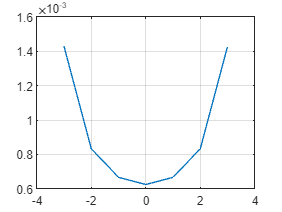

figure;
plot(x, y)
grid on;

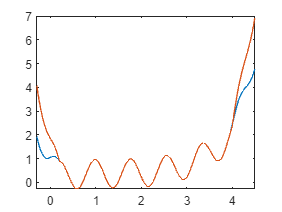

x = 2.1554

i = 2

epsilon = 1e-3;
N_max = 1000;

f= @(x) 0.2.*x+0.6.*sin(8.*x)+(0.1.*x.^2-0.5).^2;
c = 1;
c_mod = 2;
x0 = -4;
ogr = [0.2, 4];
[x, i] = find_ogr(f, x0, ogr, f_kar_zew, c, c_mod, epsilon, N_max)

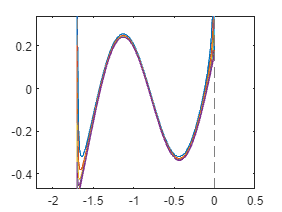

x = -1.6981

i = 11



f= @(x) 0.2.*x+0.4.*sin(4.*x)+(0.1.*x.^2-0.4).^2;
ogr = [-1.7, 0];
x0 = -1.3;
c_mod = 0.5;
[x, i] = find_ogr(f, x0, ogr, f_kar_wew, c, c_mod, epsilon, N_max)

x = -1.6981

i = 11


x0 = -1.123;
[x, i] = find_ogr(f, x0, ogr, f_kar_wew, c, c_mod, epsilon, N_max)

function [x, i] = find_ogr(f, x0, ogr, f_kar, c, c_mod, epsilon, Nmax)

    i = 1;
    x_prev = x0;
    figure;
    while(i < Nmax)
    
        f_cel = @(x_p) f(x_p) + c.*f_kar(x_p, ogr);

        fplot(f_cel, [ogr(1)-0.5, ogr(2)+0.5])
        hold on;

        x = fminsearch(f_cel, x_prev);

        if(abs(x - x_prev) < epsilon)
            return;
        end %if
        c = c_mod.*c;
        x_prev = x;
        i = i + 1;
        
    end %while

    x = realmax();
end %function

function [x_out] = f_kar_wew_handler(x, ogr)
   % Ensure x and ogr are column vectors
   x = x(:);
   ogr = ogr(:);
   % Initialize x_out to a vector of the same size as x
   x_out = zeros(size(x));
   % Apply the conditions to each element of x
   for i = 1:length(x)
       if ogr(1)<x(i) && ogr(2)>x(i)
           x_out(i) = abs( 0.01./( (x(i)-ogr(1)) .* (x(i)-ogr(2)) ) );
       else
           x_out(i) = inf;
       end
   end
end